# EPANET WQ Tests | BWFLnet_Sept2021

#### Prepared by: Yuanfei Wang

#### Date: 17 June 2022

clc
clear
close all

### Model Setup and Initialisation

Initialisation of EPANET Matlab toolkit and loading of .net file.

epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
net_id = 'BWFLnet_Sept2021';
run( [epanet_path,'\start_toolkit'])

EPANET-MATLAB Toolkit Paths Loaded.


net = epanet([net_id,'.inp']);

EPANET version {20200} loaded (EMT version {v2.2.0}).
Loading File "BWFLnet_Sept2021.inp"...
Input File "BWFLnet_Sept2021.inp" loaded sucessfuly.


### Water Age Simulation

Load network data and setup general water age simulation parameters.

% Save element count variables
nt = net.getTimeSimulationDuration./3600; % number of time steps in hours
nn = net.NodeJunctionCount;
n0 = net.NodeReservoirCount;
np = net.LinkCount; % count of pipes and valves
D = net.getLinkDiameter';

% Save node index vectors
Reservoir_Idx = net.getNodeReservoirIndex;
Junction_Idx = net.getNodeJunctionIndex;
Link_Idx = double(net.getLinkIndex);

% Initialise EPANET simulation type
net.setQualityType('Age');
net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero

% Specify hydraulic and quality time steps (in seconds)
net.setTimeQualityStep(15*60); % 15 minute quality time steps
net.setTimeHydraulicStep(15*60); % 15 minute hydraulic time steps
days = 5; % simulation duration in days; change this variable to change overall simualtion time
net.setTimeSimulationDuration(days*(nt*3600)); % load modified simulation duration from initial .inp file

quality_res_age = net.getComputedQualityTimeSeries;

% Assign quality results to network elements
c_nodes_age = quality_res_age.NodeQuality';
c_pipes_age = quality_res_age.LinkQuality';
c_time_age = quality_res_age.Time./3600';

Load network data and setup general water age simulation parameters.

% Find the maximum water age and abnormal nodes (zero demand and zero age)
% Find the maximum water age
c_limit = 0.01

c_limit = 0.0100

c_nodes_maxage = zeros(size(c_nodes_age,1),1);
for i = 1:size(c_nodes_age,1)
    c_nodes_maxage(i,1) = max(c_nodes_age(i,:));
end
c_nodes_finalage = sort(c_nodes_maxage);

for i = 1:size(c_nodes_age,1)
    for j = 1:size(c_nodes_age,2)
        if c_nodes_age(i,j) == c_nodes_finalage(nn,1)
            c_nodes_maxageIdx = i;
            break;
        end
    end
end
c_maxnode_age = c_nodes_age(c_nodes_maxageIdx,:)';
for i = 1:size(c_maxnode_age,1)
    if abs(c_maxnode_age(i,1) - c_time_age(i,1)) > c_limit
        MaxTime = c_maxnode_age(i,1);
        break
    end
end
fprintf('The maximum simulation time before periodic behaviour in the network is %.4f', MaxTime);

The maximum simulation time before periodic behaviour in the network is 63.2303

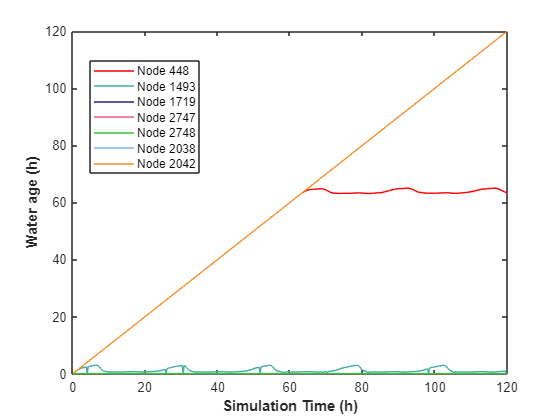


% Abonormal nodes
c_nodes_abnormalIdx = [];
c_nodes_abnormalIdx = [c_nodes_abnormalIdx;find(c_nodes_age(:,end) == 0)];
c_nodes_abnormalIdx = [c_nodes_abnormalIdx;find(abs(c_nodes_age(:,end) - double(days*nt)) <= c_limit)];

for i = 1:length(c_nodes_abnormalIdx)
    Junc_zero_Name{i} = sprintf('Node %d',c_nodes_abnormalIdx(i));
end
for i = 1:length(c_nodes_maxageIdx)
    Junc_max_Name{i} = sprintf('Node %d',c_nodes_maxageIdx(i));
end

% Plot the node with zero demand and largest water age
figure,
plot(0:0.25:days*24,c_nodes_age(c_nodes_maxageIdx,:)','-b','Color','r')
for i = 1:length(c_nodes_abnormalIdx)
    hold on
    plot(0:0.25:days*24,c_nodes_age(c_nodes_abnormalIdx(i),:)','-b','Color',[rand(),rand(),rand()]);
end

xlabel('Simulation Time (h)','FontWeight','bold')
ylabel('Water age (h)','FontWeight','bold')
legend([Junc_max_Name,Junc_zero_Name],'location','best')

% Test the abnormal nodes
c_pipes_abnormalIdx = [];
c_pipes_abnormalIdx = [c_pipes_abnormalIdx;find(c_pipes_age(:,end) == 0)];
c_pipes_abnormalIdx = [c_pipes_abnormalIdx;find(abs(c_pipes_age(:,end) - double(days*nt)) <= c_limit)];

% Test node 1493
LinkNodeIdx = net.getLinkNodesIndex;
LinktoNode1493 = find(LinkNodeIdx(:,2) == 1493);


### Chlorine Simulation

Load network data and setup general chemical simulation parameters.

% Initialise EPANET simulation type
net.setQualityType('Chemical','mg/L');
net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero

Assign chlorine decay parameters.

% Link bulk reaction coefficients
lambda = 0.5*ones(np,1); % units of days^-1
net.setLinkBulkReactionCoeff(1:np, -lambda);
net.setOptionsPipeBulkReactionOrder(1);

% Link wall decay reaction coefficients... apply by pipe size for S&G?
% theta = ones(np,1); % units of m/day
% for k = 1:np
%     if D(k) <= 75
%         theta(k) = 0.25;
%     elseif D(k) > 75 && D(k) <= 150
%         theta(k) = 0.175;
%     elseif D(k) > 150 && D(k) <= 250
%         theta(k) = 0.1;
%     else
%         theta(k) = 0.05;
%     end
% end
% 
% net.setLinkWallReactionCoeff(1:np, -theta);
% net.setOptionsPipeWallReactionOrder(1);

% Initial concentrations at nodes (mg/L)
c0 = zeros(nn+n0,nt);
net.setNodeInitialQuality(net.NodeIndex,c0);

% Assign source chlorine with time varying pattern
cext = ones(n0,4*days*nt);

% Constant source concentration for n0 reservoirs
% cext = cext*0.25;

% Varying source concentration by source element
source_c = [1.00, 0.85];

Change the chlorine pattern, whether a spike set or not.

for j = 1:n0
    cext(j,:) = source_c(j)*cext(j,:);
end

% Varying source concentration by source element with
% concentration spike (pulse) at t = 12
% t = 144;
% for i = 1:4*days*nt
%     for j = 1:n0
%         if i == t
%             cext(j,i) = 1*cext(j,i); % Pulse of 1 mg/L
%         else
%             cext(j,i) = source_c(j)*cext(j,i);
%         end
%     end
% end

base_cext = ones(n0,1); 
pattern_cext = cext./(base_cext*ones(1,size(cext,2))); % extend vector over nt columns 


% For loop to assign new patterns to source contrations at reservoirs and
% source type
for i=1:n0
    patternId = sprintf('Res_C_%d',i);
    net.addPattern(patternId,pattern_cext(i,:));
    net.setNodeSourcePatternIndex(net.NodeReservoirIndex(i),net.getPatternIndex(patternId));
    net.setNodeSourceQuality(net.NodeReservoirIndex(i),base_cext(i));
    net.setNodeSourceType(net.NodeReservoirIndex(i),'CONCEN');  
end

### Results from EPANET Simulation

Simulate hydraulic and quality analyses using EPANET's solvers.

hydraulic_res = net.getComputedHydraulicTimeSeries;
quality_res = net.getComputedQualityTimeSeries;

% Assign hydraulic results to network elements
h = hydraulic_res.Head(1:4*nt*days,1:nn).';
q = 1e-3*hydraulic_res.Flow(1:4*nt*days,:).';

% Assign quality results to network elements
c_nodes = quality_res.NodeQuality';
c_pipes = quality_res.LinkQuality';

### Graph Creation

Use graph theory to plot network connectivity and spatial coordinates.

% Create A12 and A10 incidence matrices
LinkNodesList = net.getLinkNodesIndex;

A = zeros(np,nn+n0);
for k=1:np
    i = LinkNodesList(k,1);
    j = LinkNodesList(k,2);
    A(k,i) = -1;
    A(k,j) = 1;
end

A12 = A(:,Junction_Idx);
A10 = A(:,Reservoir_Idx);
A12 = sparse(A12);
A10 = sparse(A10);

% Obstain node XY and elevation information
XY = zeros(nn+n0,2);
XY(:,1) = net.getNodeCoordinates{1};
XY(:,2) = net.getNodeCoordinates{2};
elev = double(net.getNodeElevations(Junction_Idx))';

% Create adjacency matrix
A = [A12,A10];
AdjA = sparse(size(A,2),size(A,2));

for k = 1:size(A,1)
    node_in = find(A(k,:) == -1);
    node_out = find(A(k,:) == 1);
    AdjA(node_in,node_out) = 1;
    AdjA(node_out,node_in) = 1;
end
gr = graph(AdjA);

### Results Plotting

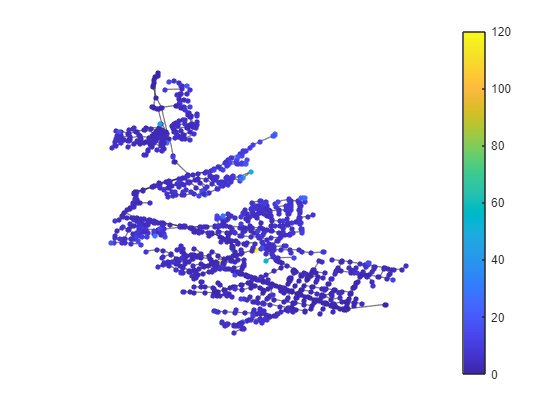

% Plot of network with zero demand junctions for visualisation
figure
i = 481;
p1 = plot(gr);
p1.XData = XY(:,1);
p1.YData = XY(:,2);
p1.LineWidth = 1;
p1.EdgeColor = 'k';
p1.MarkerSize = 3;
p1.NodeColor = 'b';
p1.NodeLabel = '';
% highlight(p1,c_nodes_abnormalIdx,'NodeColor','r','MarkerSize',8);
% labelnode(p1,c_nodes_abnormalIdx,Junc_zero_Name);
% highlight(p1,c_nodes_maxageIdx,'NodeColor','yellow','MarkerSize',8);
% labelnode(p1,c_nodes_maxageIdx,Junc_max_Name);
% highlight(p1,Reservoir_Idx,'NodeColor','k','Marker','s','MarkerSize',10);
% labelnode(p1,Reservoir_Idx,{'Reservoir','Reservoir'});
p1.NodeFontSize = 11;
p1.NodeLabelColor = [0.6350 0.0780 0.1840];
p1.NodeFontWeight = 'bold';
p1.NodeCData = c_nodes_age(:,i);
colorbar
axis('off')

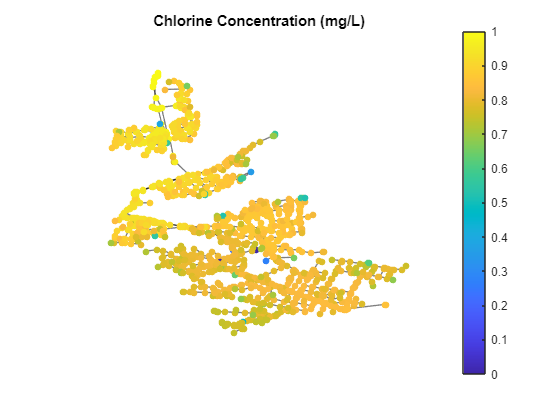


% Plot of Cl2 concentration distributed across network
% Select period to show results
i = 292;
figure
p2 = plot(gr);
p2.XData = XY(:,1);
p2.YData = XY(:,2);
p2.LineWidth = 1;
p2.EdgeColor = 'k';
p2.MarkerSize = 4;
p2.NodeLabel = '';

p2.NodeCData = c_nodes(:,i);

colorbar
axis('off')
title('Chlorine Concentration (mg/L)')

Plot time series of chlorine concentration for select junctions.

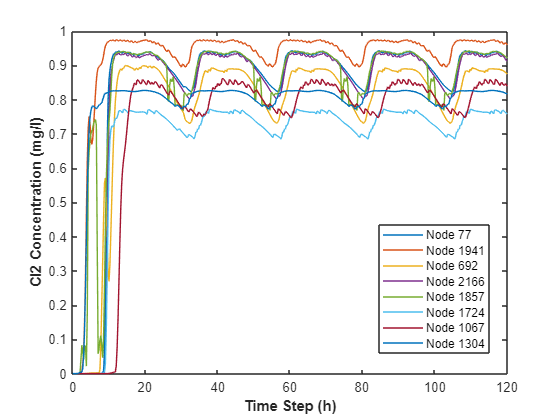

% Select junctions below
Junc_select = [77, 1941, 692, 2166, 1857, 1724, 1067, 1304];
for i = 1:length(Junc_select)
    Junct_Name{i} = sprintf('Node %d',Junc_select(i));
end
figure
for ii = 1:length(Junc_select)
        a = Junc_select(ii);
        plot(0:0.25:days*24,c_nodes(a,:)','-')
    hold on
end

legend(Junct_Name,'location','best');
xlabel('Time Step (h)','fontweight','bold')
ylabel('Cl2 Concentration (mg/l)','fontweight','bold')

### GA Calibration

First day for stabilisation, the second day for calibration, last three days for validation.

c_nodes_train = c_nodes(Junc_select,193);
c_nodes_val = c_nodes(Junc_select,194:end);
c_nodes_obs = c_nodes_train .* (1+0.001*rand(1));

mse_fun = @(sim, obs) (1/size(obs,1)/size(obs,2))*sum(sum((sim - obs).^2));
mse_original = mse_fun(c_nodes_train,c_nodes_obs);
net.getNodeActualQuality;
% calllib('epanet2','ENopenH');
% calllib('epanet2','ENinitH',0);
% tleft=1;QsH=[];t=0;T=[];
% while (tleft>0)
%     %Add code which changes something related to quality
%     [error1, t]=calllib('epanet2','ENrunH',t);
%     QsH=[QsH; calllib('epanet2','ENgetnodevalue',1,11,0)];
%     T=[T; t];
%     [error2, tleft] = calllib('epanet2','ENnextH',tleft);
% end
% calllib('epanet2','ENcloseH');
% rng default
% options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',1,'InitialPopulation', ...
%     100,'Generations',50,"ConstraintTolerance",1e-10,"PlotFcn","gaplotbestf");
% % options = optimoptions('ga','PopulationType','doubleVector','PopulationSize',1)
% Mse_function = @(x) Mse(x,c_nodes_obs,Link_Idx,Junction_Idx,Reservoir_Idx,Junc_select);
% 
% [x, fval] = ga(Mse_function,1,[],[],[],[],[],[],[],options);










